
warning('off','all')

Question: 2.a)

b1 = 3; b2 = 2.1; b3 = 0.6;
G = tf([b1,b2,b3],[1],1,"Variable","z^-1");

N = 2046; p = 3;
uk = idinput(2046,'PRBS', [0 0.2], [-1 1]);
ykstar = lsim(G,uk);
    
ek = randn([2046,1]);
noise_var = var(ykstar)/10;
yk = ykstar + ek*sqrt(noise_var);


Question: 2.b)

phi = [];
for k = 4:2047
    phi = [phi; [uk(k-1) uk(k-2) uk(k-3)]];
end

theta_hat = pinv(phi)*yk(3:end)

theta_hat =     2.9922
    2.2532
    0.4152


Question: 2.c)

y_hat = phi*theta_hat;
residual = yk(3:end) - y_hat;

noise_var_hat = sum(residual.^2)/ (N-p)

noise_var_hat = 2.7885

cov_theta_hat = inv(transpose(phi)*phi) * noise_var_hat

cov_theta_hat =     0.0038   -0.0034    0.0004
   -0.0034    0.0068   -0.0034
    0.0004   -0.0034    0.0038



for i = 1:3
    u = theta_hat(i) + 1.96*sqrt(cov_theta_hat(i,i));
    l = theta_hat(i) - 1.96*sqrt(cov_theta_hat(i,i));
    fprintf('Confidence Interval of theta%d: (%f,%f) \n',i,u,l)
end

Confidence Interval of theta1: (3.113480,2.870980) 
Confidence Interval of theta2: (2.415010,2.091336) 
Confidence Interval of theta3: (0.536759,0.293732) 


Question: 2.d) and 2.f)

theta_hat = [];
b = [b1 b2 b3];
theta_count = [0 0 0];

for i = 1:100
    uk = idinput(2046,'PRBS', [0 0.2], [-1 1]);
    ykstar = lsim(G,uk);
        
    ek = randn([2046,1]);
    noise_var = var(ykstar)/10;
    yk = ykstar + ek*sqrt(noise_var);
       
    dataset = iddata(yk,uk,1);
    [Ztrain,Tr] = detrend(dataset,0);
    
    phi = [];
    for k = 4:2047
        phi = [phi; [uk(k-1) uk(k-2) uk(k-3)]];
    end
    
    theta = pinv(phi)*yk(3:end);
    theta_hat = [theta_hat theta];
    cov_theta_hat = inv(transpose(phi)*phi) * noise_var;
    
    % Confidence 
    for i = 1:3
        u = theta(i) + 1.96*sqrt(cov_theta_hat(i,i));
        l = theta(i) - 1.96*sqrt(cov_theta_hat(i,i));
        
        if((b(i) > l) && (b(i) < u))
            theta_count(i) = theta_count(i) + 1;
        end
    end
end

mean(transpose(theta_hat))

ans =     3.0063    2.0884    0.6044


cov(transpose(theta_hat))

ans =     0.0034   -0.0026    0.0002
   -0.0026    0.0054   -0.0030
    0.0002   -0.0030    0.0034


theta_count

theta_count =     95    99    98


Question: 2.e)

% Theoretical co-variance
cov_theta_hat = inv(transpose(phi)*phi) * noise_var

cov_theta_hat =     0.0038   -0.0034    0.0004
   -0.0034    0.0069   -0.0034
    0.0004   -0.0034    0.0039


Question: 2.g)

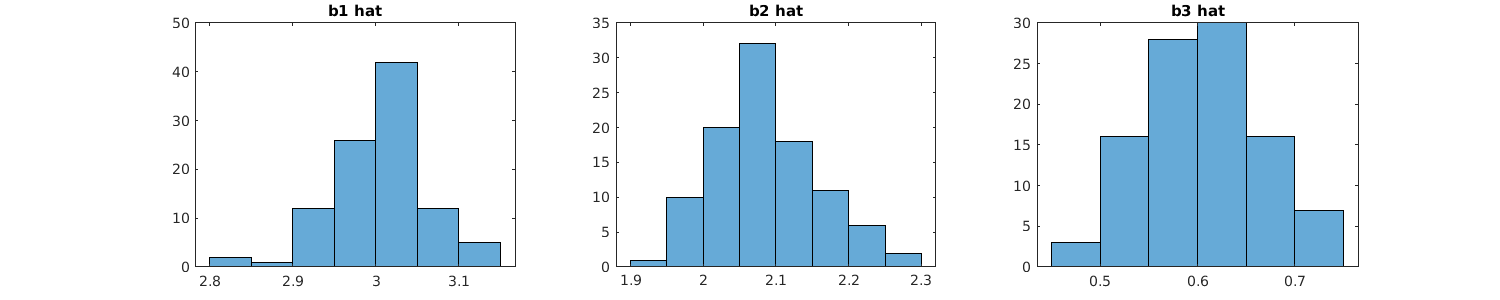

set(gcf,'position',[10,10,1500,300])

subplot(1,3,1);
histogram(theta_hat(1,:));
title('b1 hat');

subplot(1,3,2);
histogram(theta_hat(2,:));
title('b2 hat');

subplot(1,3,3);
histogram(theta_hat(3,:));
title('b3 hat');

Question: 3.a)

mod_p = idpoly (1, [0,0,0,2,0.6], 1, [1 -0.5], [1,-1.2,0.32],'Noisevariance', 1,'Ts',1)

mod_p =


uk = idinput(1530,'PRBS', [0 0.15], [-1 1]);

% Calculate yk_star:
yk_star = sim(mod_p ,uk);

% Calculate variance of e[k] such that var(yk_star)/var(v[k]) = 10
mod_p.Noisevariance = var(yk_star) * 0.075;
yk = sim(mod_p ,uk , simOptions ('AddNoise',true));


Question: 3.b)

% Train-Test split:
dataset = iddata(yk ,uk ,1);
datatrain = dataset (1:1000); datatest = dataset (1001:end);
[Ztrain ,Tr] = detrend(datatrain, 0);
Ztest = detrend(datatest, Tr);

% 99 % significance levels
clim = 2.58/sqrt(length(Ztrain.y));

Question: 3.c)

% ARX model:
mod_arx = arx(Ztrain, [2 3 3]);
present(mod_arx)
yhat_arx = predict(mod_arx, Ztrain );      % Predictions on training data
err_arx = pe(mod_arx , Ztrain );           % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_arx = xcov(err_arx.y, Ztrain.u, 100,'coeff');
acf_arx = xcov(err_arx.y,50,'coeff');

% Plot
figure;set(gcf,'position',[10,10,1000,900]);

subplot(311); stem( -100:100 , cross_corr_arx ); hold on
plot([ -100 100] ,[1 1]* clim ,'r--' ,[-100 100], [ -1 -1]*clim ,'g--')
title('Correlation between residuals and inputs (ARX Model)')

subplot(312); stem((0:50) ,acf_arx (51:end)); hold on
plot([0 50] ,[1 1]* clim ,'r--' ,[0 50] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (ARX Model)')

subplot(313)
test_prediction = predict(mod_arx, Ztest);
plot(test_prediction.y, Ztest.y, 'x', Ztest.y, Ztest.y, 'r-');
title('Predictions on test data')
R_squared = 1 - norm(Ztest.y - test_prediction.y)/norm(Ztest.y - mean(Ztest.y))

% OE model:
mod_oe = oe(Ztrain ,[2 1 3]);
present(mod_oe)
yhat_oe = predict(mod_oe , Ztrain );       % Predictions on training data
err_oe = pe(mod_oe , Ztrain );             % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_oe = xcov(err_oe.y, Ztrain.u,25,'coeff');
acf_oe = xcov(err_oe.y,20,'coeff');

% Plot
figure;set(gcf,'position',[10,10,1000,900]);

subplot(311); stem( -25:25 , cross_corr_oe ); hold on
plot([ -25 25] ,[1 1]* clim ,'r--' ,[-25 25] ,[ -1 -1]*clim ,'g--')
title('Correlation between residuals and inputs (OE Model)')

subplot(312); stem((0:20) ,acf_oe (21:end)); hold on
plot([0 20] ,[1 1]* clim ,'r--' ,[0 20] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (OE Model)')

subplot(313)
test_prediction = predict(mod_oe, Ztest);
plot(test_prediction.y, Ztest.y, 'x', Ztest.y, Ztest.y, 'r-');
title('Predictions on test data')
R_squared = 1 - norm(Ztest.y - test_prediction.y)/norm(Ztest.y - mean(Ztest.y))
% BJ model:
mod_bj = bj(Ztrain ,[2 0 1 1 3]);
present(mod_bj)
yhat_bj = predict(mod_bj, Ztrain );       % Predictions on training data
err_bj = pe(mod_bj, Ztrain );             % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_bj = xcov(err_bj.y, Ztrain.u,25,'coeff');
acf_bj = xcov(err_bj.y,20,'coeff');

% Plot
figure;set(gcf,'position',[10,10,1000,900]);

subplot(311); stem( -25:25 , cross_corr_bj ); hold on
plot([ -25 25] ,[1 1]* clim ,'r--' ,[-25 25] ,[ -1 -1]*clim ,'g--')
title('Correlation between residuals and inputs (BJ Model)')

subplot(312); stem((0:20) ,acf_bj (21:end)); hold on
plot([0 20] ,[1 1]* clim ,'r--' ,[0 20] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (BJ Model)')

subplot(313)
test_prediction = predict(mod_bj, Ztest);
plot(test_prediction.y, Ztest.y, 'x', Ztest.y, Ztest.y, 'r-');
title('Predictions on test data')
R_squared = 1 - norm(Ztest.y - test_prediction.y)/norm(Ztest.y - mean(Ztest.y))

Question: 4.a)

iodata= load("a5_inoutdata.mat");
% Check for Integrating effects:
figure;set(gcf,'position',[10,10,1000,600]);

subplot(2,1,1)
plot(iodata.yk)

subplot(2,1,2)
plot(iodata.yk(2:end) - iodata.yk(1:end-1))
% Estimating delay using impulse responses
irestoptions = impulseestOptions;
irestoptions.Advanced.AROrder = 0;
mod_ir = impulseest(iddata(iodata.yk, iodata.uk, 1),irestoptions);

% Plot the IR coefficients
[ircoeff,kvec,q,ir_sd] = impulse(mod_ir,70);
figure;
stem(kvec,ircoeff,'Markerfacecolor','blue');

Removing integrating effects:

% Train-Test split: (removing integrating effects)
dataset = iddata(iodata.yk(2:end) - iodata.yk(1:end-1) ,iodata.uk(2:end) - iodata.uk(1:end-1) ,1);
datatrain = dataset (1:1500); datatest = dataset (1501:end);
[Ztrain ,Tr] = detrend(datatrain, 0);
Ztest = detrend(datatest, Tr);

% 99 % significance levels
clim = 2.58/sqrt(length(Ztrain.y));

OE model: (white-noise assumption)

% OE model:
mod_oe = oe(Ztrain ,[1 1 2]);
present(mod_oe);
yhat_oe = predict(mod_oe , Ztrain );       % Predictions on training data
err_oe = pe(mod_oe , Ztrain );             % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_oe = xcov(err_oe.y, Ztrain.u,25,'coeff');
acf_oe = xcov(err_oe.y,20,'coeff');

% Plot
figure;set(gcf,'position',[10,10,1000,600]);

subplot(211); stem( -25:25 , cross_corr_oe ); hold on
plot([ -25 25] ,[1 1]* clim ,'r--' ,[-25 25] ,[ -1 -1]*clim ,'g--')
title('Correlation between residuals and inputs (OE Model)')
ylim([-0.1 0.1])
subplot(212); stem((0:20) ,acf_oe (21:end)); hold on
plot([0 20] ,[1 1]* clim ,'r--' ,[0 20] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (OE Model)')

BJ model:

% BJ model:
mod_bj = bj(Ztrain ,[1 1 1 1 2]);
present(mod_bj)
yhat_bj = predict(mod_bj, Ztrain );       % Predictions on training data
err_bj = pe(mod_bj, Ztrain );             % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_bj = xcov(err_bj.y, Ztrain.u,25,'coeff');
acf_bj = xcov(err_bj.y,20,'coeff');

% Plot
figure;set(gcf,'position',[10,10,1000,600]);

subplot(211); stem( -25:25 , cross_corr_bj ); hold on
plot([ -25 25] ,[1 1]* clim ,'r--' ,[-25 25] ,[ -1 -1]*clim ,'g--')
title('Correlation between residuals and inputs (BJ Model)')
ylim([-0.4 0.4])

subplot(212); stem((0:20) ,acf_bj (21:end)); hold on
plot([0 20] ,[1 1]* clim ,'r--' ,[0 20] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (BJ Model)')
% Predictions on test data
yhat_bj = predict(mod_bj, Ztest);

figure;set(gcf,'position',[10,10,1000,600]);
plot(linspace(1501,2045,545), Ztest.y, 'black'); hold on
plot(linspace(1501,2045,545), yhat_bj.y, 'r--');
legend('Original','Predicted');

Question: 4.b)

Without removing integrating effects:

% Train-Test split:
dataset = iddata(iodata.yk, iodata.uk, 1);
datatrain = dataset (1:1500); datatest = dataset (1501:end);
[Ztrain ,Tr] = detrend(datatrain, 0);
Ztest = detrend(datatest, Tr);

% 99 % significance levels
clim = 2.58/sqrt(length(Ztrain.y));

OE model: (white-noise assumption)

% OE model:
mod_oe = oe(Ztrain ,[1 1 2]);
present(mod_oe);
yhat_oe = predict(mod_oe , Ztrain );       % Predictions on training data
err_oe = pe(mod_oe , Ztrain );             % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_oe = xcov(err_oe.y, Ztrain.u,25,'coeff');
acf_oe = xcov(err_oe.y,20,'coeff');

% Plot
figure;set(gcf,'position',[10,10,1000,600]);

subplot(211); stem( -25:25 , cross_corr_oe ); hold on
plot([ -25 25] ,[1 1]* clim ,'r--' ,[-25 25] ,[ -1 -1]*clim ,'g--')
title('Correlation between residuals and inputs (OE Model)')
ylim([-0.4 0.4])

subplot(212); stem((0:20) ,acf_oe (21:end)); hold on
plot([0 20] ,[1 1]* clim ,'r--' ,[0 20] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (OE Model)')

BJ model:

% BJ model:
% [1 3 3 1 2] --> [1 1 2 1 2]
mod_bj = bj(Ztrain ,[1 1 2 1 2]);
present(mod_bj)
yhat_bj = predict(mod_bj, Ztrain );       % Predictions on training data
err_bj = pe(mod_bj, Ztrain );             % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_bj = xcov(err_bj.y, Ztrain.u,25,'coeff');
acf_bj = xcov(err_bj.y,20,'coeff');

% Plot
figure;set(gcf,'position',[10,10,1000,600]);

subplot(211); stem( -25:25 , cross_corr_bj ); hold on
plot([ -25 25] ,[1 1]* clim ,'r--' ,[-25 25] ,[ -1 -1]*clim ,'g--')
title('Correlation between residuals and inputs (BJ Model)')
ylim([-0.4 0.4])

subplot(212); stem((0:20) ,acf_bj (21:end)); hold on
plot([0 20] ,[1 1]* clim ,'r--' ,[0 20] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (BJ Model)') 

% Predictions on test data
yhat_bj = predict(mod_bj, Ztest);

figure;set(gcf,'position',[10,10,1000,600]);
plot(linspace(1501,2046,546), Ztest.y, 'black'); hold on
plot(linspace(1501,2046,546), yhat_bj.y, 'r--');
legend('Original','Predicted');


Question: 5.a)

% Increase precision of double to 200 (whichever is enclosed by vpa() function)
d1 = digits(200);

N = 100;
mod_p = idpoly(1, [0 2 1.4], 1, 1, 1,'Noisevariance', 1,'Ts',1);
uk = idinput(N+2,'PRBS', [0 1], [-1 1]);

% Calculate yk_star:
yk_star = sim(mod_p ,uk);
mod_p.Noisevariance = var(yk_star) / 10;

% Calculate yk:
yk = sim(mod_p ,uk , simOptions ('AddNoise',true));


syms y mu stdev
pdf_guassian = ((1/sqrt(2*pi*stdev.^2))*exp(-(((y-mu)/stdev).^2)/2));

syms b1 b2 mu1 mu2 stdev1 stdev2
joint_gaussian_pdf = ((1/sqrt(2*pi*stdev1.^2))*exp(-(((b1-mu1)/stdev1).^2)/2)).*((1/sqrt(2*pi*stdev2.^2)).*exp(-(((b2-mu2)/stdev2).^2)/2));

likelihood = 1;
for k = 3:N+2
    pdf_yk = subs(pdf_guassian, {y,mu,stdev},  {yk(k), b1*uk(k-1) + b2*uk(k-2), sqrt(var(yk))});
    likelihood = likelihood .* pdf_yk;
end


prior = subs(joint_gaussian_pdf, {mu1, mu2, stdev1, stdev2}, {0, 0, 5, 5})
f_yn = vpa(integral2(matlabFunction(likelihood .* prior), -Inf, Inf, -Inf, Inf));
posterior = (1/f_yn) * vpa(likelihood * prior);

mom_1 = matlabFunction(b1 .* posterior);
mom_2 = matlabFunction(b1^2 .* posterior);

integral2(mom_1, -Inf, Inf, -Inf, Inf)

mom_1 = matlabFunction(b2 .* posterior);
integral2(mom_1, -Inf, Inf, -Inf, Inf)